道路情報カメラで取得した画像データの処理プログラム

初期データリセット

clc, clear; close all;

道路画像をインプットし，道路情報のみを保存する部分

"simple_separate.m"

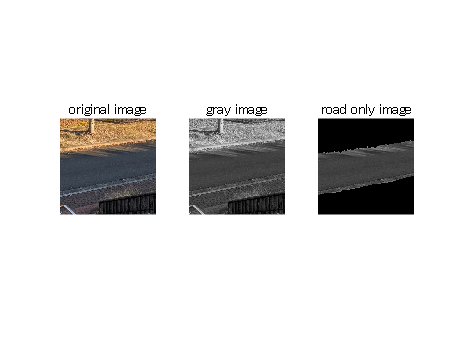

% 道路画像(GRBカラー)
img_in = double(imread("road_image2.bmp"));
% 道路のみのマスク
road_mask = table2array(readtable("road_image2_mask.xlsx"));

% カラー画像を白黒に変換
img_gray = 0.299*img_in(:,:,1) + 0.587*img_in(:,:,2) + 0.114*img_in(:,:,3);

% 白黒画像に対してマスクを畳み込み
img_road = img_gray .* road_mask;


figure()
% 元画像の表示
subplot(1,3,1);
imshow(uint8(img_in));
title("original image");
% 白黒画像の表示
subplot(1,3,2);
imshow(uint8(img_gray));
title("gray image");
% 道路のみの画像を表示
subplot(1,3,3);
imshow(uint8(img_road));
title("road only image");

画像すべてをブロック化及び，

道路のみの画像をブロック(16×16)に変換する部分

"road_to_block.m"

% ブロックに変えるサイズ設定(変更可能にする予定)
size_b = 16;

size_x = size(img_road,2)/size_b;
size_y = size(img_road,1)/size_b;

block_num = [];     % ブロック化した番号を保存
block_count = size_x * size_y;

% 初期値設定
count = 1;
count_road = 1;
flag = 0;
block_all = zeros(size_b, size_b, size_x*size_y);

% グレー画像と道路のみ画像をブロック化
for i = 1:size_y
    for j = 1:size_x
        block_all(:,:,count) = img_gray((i-1)*size_b+1:i*size_b, (j-1)*size_b+1:j*size_b);
        block_all_road(:,:,count) = img_road((i-1)*size_b+1:i*size_b, (j-1)*size_b+1:j*size_b);
        if block_all_road(1,1,count) == 0
            flag = 1;
        elseif block_all_road(1,size_b,count) == 0
            flag = 1;
        elseif block_all_road(size_b,1,count) == 0
            flag = 1;
        elseif block_all_road(size_b,size_b,count) == 0
            flag = 1;
        end

        if flag == 0
            block_road(:,:,count_road) = img_road((i-1)*size_b+1:i*size_b, (j-1)*size_b+1:j*size_b);
            block_num = [block_num, count];
            count_road = count_road + 1;
        end
        count = count + 1;
        flag = 0;
    end
end

clearvars block_all_road;

道路情報の部分のみVAEに通過させる．

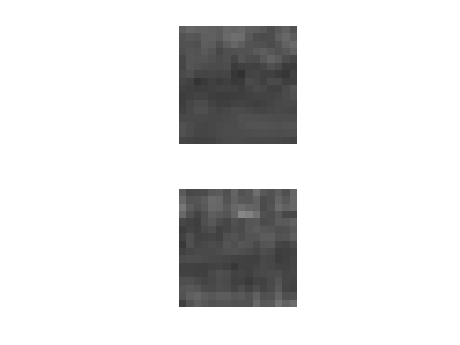

rng(2025);          % Set random seed.

input_count = 1024;

% Step size
eta = 0.0001;   %学習率が高すぎると更新した係数が大きくなりすぎてコストが減らなくなる
epoch = 10000;  %実行回数

% レイヤーの設定
Layer1 = size_b*size_b;         % 入力層のユニット数
Layer2 = 32;                    % 中間層（隠れ層，AEの出力層）のユニット数
Layer3 = Layer1;                % 復元層（出力層）のユニット数

L2func = 'ReLUfnc';             % 中間層のアルゴリズム（'Sigmoid' or Default: 'ReLUfnc' 文字数は等しくないとエラーを起こす）
L3func = 'Sigmoid_BCE';         % 復元層のアルゴリズムと誤差（'Sigmoid_MSE' or Default : 'Sigmoid_BCE' (Binary Cross Entropy)）

block_num_size = size(block_num,2);
block_all_size = size(block_all,3);

% 道路の情報のみをNew64_1に格納
New64_1(:,:,:) = block_road/255.0;
% すべての画像をNew64_2に格納
New64_2(:,:,:) = block_all/255.0;


figure(100); 
%subplot(2,1,1);
%imshow(New64(:,:,1));
%subplot(2,1,2);imshow(New64(:,:,2));
for i = 1:2
    subplot(2,1,i);
    imshow(New64_1(:,:,i));
end



%% 教師データを縦ベクトルにし，LabelDataに格納
% 横方向に順に並べた縦ベクトルを作るには、'をつけておく
TrainData = zeros(size_b*size_b, block_num_size);
LabelData = zeros(size_b*size_b, block_num_size);
TestData = zeros(size_b*size_b, block_all_size);
TLabelData = zeros(size_b*size_b, block_all_size);
for i = 1:block_num_size
    TrainData(:,i) = reshape(New64_1(:,:,i)', size_b*size_b,1);
    LabelData(:,i) = TrainData(:,i); 
end

%% テストデータの入力
for i = 1:1024
    TestData(:,i) = reshape(New64_2(:,:,i)', size_b*size_b,1);
    TLabelData(:,i) = TestData(:,i);
end

%% 中間層と出力層の重みの初期値
% Initialization values of weights (Hidden layer and Output layer)

w12_mean = randn(Layer2,Layer1);	% 教師データ用の行列(中間層1の重み)	 hidden layer's weight matrix for supervisor data
w12_var = randn(Layer2,Layer1);	% 教師データ用の行列(中間層1の重み)	 hidden layer's weight matrix for supervisor data
w23 = randn(Layer3,Layer2);	% 教師データ用の行列(復元層２の重み)	hidden layer's weight matrix for supervisor data

% 中間層と出力層のバイアスの初期値
% Initialization values of bias (Hidden layer and Output layer) 
b2_mean = randn(Layer2,1);
b2_var = randn(Layer2,1);
b3 = randn(Layer3,1);

%%
% 初期状態における a3 の出力
% Forward Process (Initial weight)
X = TestData;
t = TLabelData;

%[z2_mean,z2_var, a2_mean, a2_var,z,z3,a3] = Neuralnetwork2_forward_VAE(X,w12_mean,w12_var,w23,b2_mean,b2_var,b3);

fprintf('Initial Weight\n');

Initial Weight


% fprintf('w12_mean\n');   disp(w12_mean);
% fprintf('w12_var\n');   disp(w12_var);
% fprintf('b2_mean\n');    disp(b2_mean);
% fprintf('b2_var');    disp(b2_var);
% fprintf('w23\n');   disp(w23);
% fprintf('b3\n');    disp(b3);

fprintf('Initial Weight Test\n');

Initial Weight Test


1000/10000
2000/10000
3000/10000
4000/10000
5000/10000
6000/10000
7000/10000
8000/10000
9000/10000
10000/10000


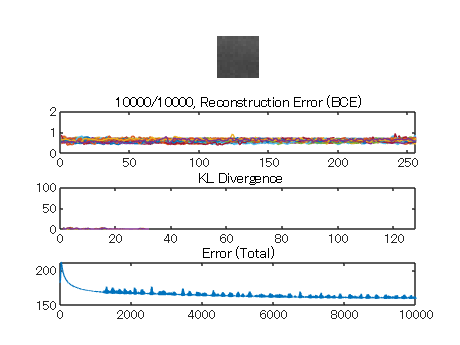

% fprintf('Test data X \n');   disp(X);
% fprintf('z2_mean\n');    disp(z2_mean);
% fprintf('a2_mean\n');    disp(a2_mean);
% fprintf('z2_var\n');    disp(z2_var);
% fprintf('a2_var\n');    disp(a2_var);
% fprintf('z\n');    disp(z);
% fprintf('z3\n');    disp(z3);
% fprintf('a3\n');    disp(a3);

%figure(101);
%for j = 1:2
%    subplot(2,1,j);
%    imshow(reshape(a3(:,j), [16 16])');
%end

% 学習前の初期ウェイトと初期バイアスにおけるテストにおける中間層の分布のグラフ表示
% figure(1);
% hold on;
% for i=1:7
%     plot(z(1,i), z(2,i),'or');
% end
% for i=8:14
%     plot(z(1,i), z(2,i),'xk');
% end
% hold off;
% xlabel('y_1 = z_1'); ylabel('y_2 = z_2');
% title('Latent Variable (Initial weights and bias)');
% box('on');

%% VAE の学習
tic;
X = TrainData;
t = LabelData;
[w12_mean,w12_var,w23,b2_mean,b2_var,b3,w12_mean_t,w12_var_t,w23_t,b2_mean_t,b2_var_t,b3_t,C] = Neuralnetwork2_VAE(X,t,w12_mean,w12_var,w23,b2_mean,b2_var,b3,eta,epoch,L2func,L3func);

toc

経過時間は 93.933054 秒です。





% 値の表示
fprintf('Final Weight\n');

Final Weight


% fprintf('w12_mean\n');   disp(w12_mean);
% fprintf('b2_mean\n');    disp(b2_mean);
% fprintf('w12_var\n');   disp(w12_var);
% fprintf('b2_var\n');    disp(b2_var);
% fprintf('w23\n');   disp(w23);
% fprintf('b3\n');    disp(b3);

fprintf('Final Weight Test\n');

Final Weight Test


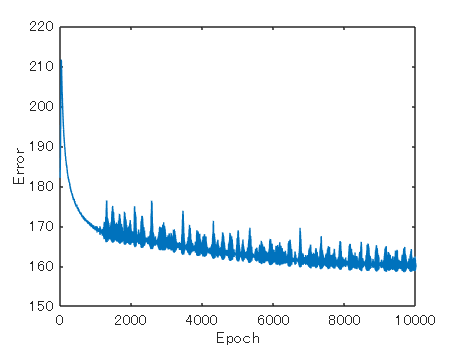

% fprintf('Test data X \n');   disp(X);
% fprintf('a2_mean\n');    disp(a2_mean);
% fprintf('a2_var\n');    disp(a2_var);
% fprintf('z\n');    disp(z);
% fprintf('z3\n');    disp(z3);
% fprintf('a3\n');    disp(a3);


% 学習後のテスト入力における中間層の分布のグラフ表示
%figure(2);
%hold on;
%for i=1:input_count
%     plot3(z(1,i), z(2,i), z(3,i),'or');
%end
%xlabel('z1'); ylabel('z2'); zlabel('z3');
%grid on;

% for i=8:14
%     plot(z(1,i), z(2,i),'xk');
% end
% hold off;
% xlabel('y_1 = z_1'); ylabel('y_2 = z_2');
% title('Latent Variable (Final weights and bias)');
% % xlim([0 ceil(max(a2(1,:))/10)*10]);
% % ylim([0 ceil(max(a2(2,:))/10)*10]);
% box('on');
% 
% figure(1);
% xlim([0 ceil(max(a2(1,:))/10)*10]);
% ylim([0 ceil(max(a2(2,:))/10)*10]);

% 学習過程のグラフ表示（各エポックごとのの誤差関数の値）
figure(3);
plot(C);
xlabel('Epoch'); ylabel('Error');


% z = [0 1 3 4 5 6 7 8];
% [z3,a3] = Neuralnetwork_generate_VAE(z, w23,b3)
% fprintf('Generation \n');
% fprintf('z\n');    disp(z);
% fprintf('z3\n');    disp(z3);
% fprintf('a3\n');    disp(a3);

%% ブロック番号をエクセルに仮保存
%writematrix(a3, "fulla3_output.xlsx");


VAE学習後，全ての画像をVAEに通過させる

%% 学習後のテスト
X = TestData;

[z2_mean,z2_var, a2_mean, a2_var,z,z3,a3] = Neuralnetwork2_forward_VAE(X,w12_mean,w12_var,w23,b2_mean,b2_var,b3);

VAE通過後のブロックを結合させ，元の画像との比較

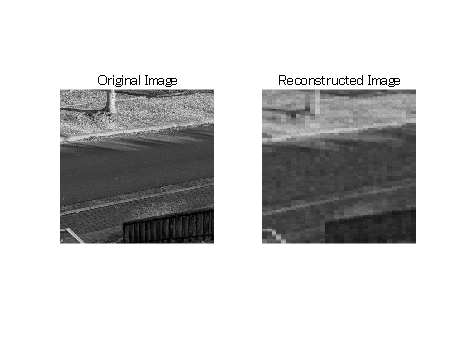

% 縦ベクトルをブロックに変換
for i = 1:1024
    % 16×16行列に変換
    %num = block_num(1,i);
    block_all_ret(:,:,i) = reshape(a3(:,i), [16, 16])';
end

% ブロックを結合
count = 1;
for i = 1:size_y
    for j = 1:size_x
        % 元の画像に配置
        img_ret((i-1)*size_b+1:i*size_b, (j-1)*size_b+1:j*size_b) = block_all_ret(:,:,count) * 255.0;
        count = count + 1;
    end
end

figure()
subplot(1,2,1);
imshow(uint8(img_gray));
title('Original Image');
subplot(1,2,2);
imshow(uint8(img_ret));
title('Reconstructed Image');


imwrite(img_ret,"output_test.bmp");

ブロック毎と全体のPSNRを測定

MSE = sum(sum(abs(img_ret(:,:) - img_gray(:,:)).^2))/(size_b*size_b);
PSNR = 10*log10((255)^2/MSE);
fprintf("MSE = %.3f , PSNR = %.3f [dB]\n", MSE, PSNR);

MSE = 402329.082 , PSNR = -7.915 [dB]



block_PSNR = [];

%% ブロック毎のPSNRの比較
for i = 1:block_count
    block_1 = block_all(:,:,i);
    block_2 = block_all_ret(:,:,i);

    diff = abs((block_1 - block_2).^2);
    PSNR_c = 0;
    % MSE, PSNRの測定
    for j = 1:16
        for k = 1:16
            PSNR_c = PSNR_c+diff(j,k);
        end
    end
    MSE = PSNR_c / (16*16);
    PSNR = 10*log10((255)^2/MSE);
    
    block_PSNR = [block_PSNR, PSNR];
end

block_PSNR_mat = reshape(block_PSNR, 32, 32)';
writematrix(block_PSNR_mat, "block_PSNR.xlsx");

fprintf("program complete\n");

program complete
